# MTI Toolbox

clear all;
close all;


## Construction workflow

F = 1;
F_Phi = 2;

G = 3;
G_Phi = 4;

ts = 1;

system1 = mss(CPN1(F,F_Phi),ts)

system1 =   mss with properties:

        F: [1×1 norm1CPN]
        G: [0×0 mtiTens]
        n: 1
        m: 0
        p: 0
    ntype: '1'
       ts: 1


system2 = mss(CPN1(F,F_Phi),CPN1(G,G_Phi),ts)

system2 =   mss with properties:

        F: [1×1 norm1CPN]
        G: [1×1 norm1CPN]
        n: 1
        m: 0
        p: 1
    ntype: '1'
       ts: 1


F1 = system1.F

F1 =   norm1CPN with properties:

      U: 1
    phi: 2


G1 =system2.G

G1 =   norm1CPN with properties:

      U: 3
    phi: 4


Desirable Use-case 


% Big-Picture Goals

% MSim equivalent parameters as lsim

% overload matlab's linearize 

% Prioritize c2d over d2c

% Nice to use: ss as input to constructor

% Sparse models have to be compatible with the structure



bool test

    bsys = drmss(2,2,2,2,0.2,1)

bsys = struct with fields:
    n: 2
    F: [1×1 struct]
    G: [1×1 struct]


    msys = mss(CPN1(bsys.F.U,bsys.F.phi),CPN1(bsys.F.U,bsys.G.phi),ts)

msys =   mss with properties:

        F: [1×1 norm1CPN]
        G: [1×1 norm1CPN]
        n: 2
        m: 2
        p: 2
    ntype: '1'
       ts: 1


    x0 = [ 0;0];
    u = [0 1 2 3 4; 0 1 2 3 4];
    t = 5;

    [y_sim_legacy_b, x_sim_legacy_b] = legacyMsim(bsys,u,t,x0)

y_sim_legacy_b =          0         0         0         0         0
    0.6490    0.6490    1.5657    3.3991    6.1493


x_sim_legacy_b =          0         0    0.4711    0.9422    1.4133    1.8844
         0         0         0         0         0         0


    [y_sim_b, x_sim_b] = legacyMsim(msys,u,t,x0)

y_sim_b =          0         0         0         0         0
         0    1.6220    3.2439    4.8659    6.4879


x_sim_b =          0         0    0.4711    0.9422    1.4133    1.8844
         0         0         0         0         0         0



    
    [y_result_b,~, x_result_b]= msim(msys,u',t,x0,true)

y_result_b =          0         0
         0    1.6220
         0    3.2439
         0    4.8659
         0    6.4879


x_result_b =          0         0
         0         0
    0.4711         0
    0.9422         0
    1.4133         0
    1.8844         0


double test

    dataFile = "simMTITest" + "Data.mat";
    sys = load(dataFile).sys;
    msys = mss(CPN1(sys.F.U,sys.F.phi),CPN1(sys.F.U,sys.G.phi),ts);
    x0 = [ 0;0];
    u = [0 1 2 3 4; 0 1 2 3 4];
    t = 5;

    [y_sim_legacy, x_sim_legacy] = legacyMsim(sys,u,t,x0)

y_sim_legacy =     1.1769    1.1997    1.2224    1.2452    1.2680
    0.0745    0.0793    0.0840    0.0887    0.0934


x_sim_legacy =          0         0         0         0         0         0
         0    0.1985    0.5186    0.8387    1.1587    1.4788


    [y_sim, x_sim] = legacyMsim(msys,u,t,x0)

y_sim =     0.5952    1.5400    2.4848    3.4296    4.3745
    0.0573    0.1499    0.2424    0.3350    0.4276


x_sim =          0         0         0         0         0         0
         0    0.1985    0.5186    0.8387    1.1587    1.4788



    
    [y_result,~,x_result]= msim(msys,u',t,x0,true)

y_result =     0.5952    0.0573
    1.5400    0.1499
    2.4848    0.2424
    3.4296    0.3350
    4.3745    0.4276


x_result =          0         0
         0    0.1985
         0    0.5186
         0    0.8387
         0    1.1587
         0    1.4788


full(non-sparse) test 

    dataFile = "simMTITest" + "Data.mat";
    sys = load(dataFile).sys;

    sys.F.U = full(sys.F.U)

sys = struct with fields:
    n: 2
    F: [1×1 struct]
    G: [1×1 struct]


    sys.F.phi = full(sys.F.phi)

sys = struct with fields:
    n: 2
    F: [1×1 struct]
    G: [1×1 struct]



    sys.G.U = full(sys.G.U)

sys = struct with fields:
    n: 2
    F: [1×1 struct]
    G: [1×1 struct]


    sys.G.phi = full(sys.G.phi)

sys = struct with fields:
    n: 2
    F: [1×1 struct]
    G: [1×1 struct]



    msys = mss(CPN1(sys.F.U,sys.F.phi),CPN1(sys.F.U,sys.G.phi),ts);
    x0 = [ 0;0];
    u = [0 1 2 3 4; 0 1 2 3 4];
    t = 5;

    [y_sim_legacy, x_sim_legacy] = legacyMsim(sys,u,t,x0)

y_sim_legacy =     1.1769    1.1997    1.2224    1.2452    1.2680
    0.0745    0.0793    0.0840    0.0887    0.0934


x_sim_legacy =          0         0         0         0         0         0
         0    0.1985    0.5186    0.8387    1.1587    1.4788


    [y_sim, x_sim] = legacyMsim(msys,u,t,x0)

y_sim =     0.5952    1.5400    2.4848    3.4296    4.3745
    0.0573    0.1499    0.2424    0.3350    0.4276


x_sim =          0         0         0         0         0         0
         0    0.1985    0.5186    0.8387    1.1587    1.4788



    
    [y_result_full, ~,x_result_full]= msim(msys,u',t,x0,true)

y_result_full =     0.5952    0.0573
    1.5400    0.1499
    2.4848    0.2424
    3.4296    0.3350
    4.3745    0.4276


x_result_full =          0         0
         0    0.1985
         0    0.5186
         0    0.8387
         0    1.1587
         0    1.4788


fulltens test

    dataFile = "simMTITest" + "Fultensor.mat";
    F = load(dataFile).S;
    
    
    msys = mss(F,ts)

msys =   mss with properties:

        F: [1×1 norm1CPN]
        G: [0×0 mtiTens]
        n: 2
        m: 1
        p: 0
    ntype: '1'
       ts: 1


    x0 = [ 0;0];
    u = [0 1 2 3 4];
    t = 5;

    %[y_sim_legacy, x_sim_legacy] = msim(sys,u,t,x0)
    %[y_sim, x_sim] = legacyMsim(msys,u,t,x0)
    
    
    [y_result_full,~, x_result_full]= msim(msys,u',t,x0)

y_result_full =            0           0
           1           3
           3          30
           5         401
           7        7308
           9      175551


x_result_full =            0           0
           1           3
           3          30
           5         401
           7        7308
           9      175551


continuous-time simulation:

    ts = 0;
    msys = mss(F, ts)

msys =   mss with properties:

        F: [1×1 norm1CPN]
        G: [0×0 mtiTens]
        n: 2
        m: 1
        p: 0
    ntype: '1'
       ts: 0


    x0 = [0;0];
    u = [0 1 2 3 4];
    t = 1:5;

    [y_result_full,~, x_result_full]= msim(msys,u',t,x0)

y_result_full = 1.0e+21 *

         0         0
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000


x_result_full = 1.0e+21 *

         0         0
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000


continuous linear model in mti simulation:

    F = CPN1([1 0; 0 1], [1/5 2/5]);
    G = CPN1([1 0; 0 1], [3 4]);
    
    msys = mss(F,G)

msys =   mss with properties:

        F: [1×1 norm1CPN]
        G: [1×1 norm1CPN]
        n: 1
        m: 1
        p: 1
    ntype: '1'
       ts: 0


    x0 = [1];
    u = 0.1*(rand([10,1])-0.5);
    t = 0:length(u)-1;

    [y_mlin,t_mlin,x_mlin] = msim(msys, u, t, x0);

    A = 1/5;
    B = 2/5;
    C = 3;
    D = 4;
    lsys = ss(A,B,C,D)

lsys =
 
  A = 
        x1
   x1  0.2
 
  B = 
        u1
   x1  0.4
 
  C = 
       x1
   y1   3
 
  D = 
       u1
   y1   4
 
Continuous-time state-space model.



    [y_lin, t_lin, x_lin] = lsim(lsys, u, t,x0);
    
    figure()
    hold on
    plot(t_mlin, y_mlin,'-')
    plot(t_lin, y_lin,'--')
    legend('msim', 'lsim')
    hold off

2 states/ 2 inputs / 2 outputs example

    A = [1/5 0; -2/5 3/5];
    B = [2/5 0; 0 -1/3];
    C = [3 0; 0 1];
    D = [0.04 0; 0 0];
    lsys = ss(A, B, C, D)

lsys =
 
  A = 
         x1    x2
   x1   0.2     0
   x2  -0.4   0.6
 
  B = 
            u1       u2
   x1      0.4        0
   x2        0  -0.3333
 
  C = 
       x1  x2
   y1   3   0
   y2   0   1
 
  D = 
         u1    u2
   y1  0.04     0
   y2     0     0
 
Continuous-time state-space model.




    x0 = [1; 1];
    u = 0.1*(rand([10,2])-0.5);
    t = 0:length(u(:,1))-1;

    [y_lin, t_lin, x_lin] = lsim(lsys, u, t, x0, 'foh');

    F = CPN1(diag(ones([4,1])), [A B]);
    G = CPN1(diag(ones([4,1])), [C D]);
    
    msys = mss(F,G)

msys =   mss with properties:

        F: [1×1 norm1CPN]
        G: [1×1 norm1CPN]
        n: 2
        m: 2
        p: 2
    ntype: '1'
       ts: 0


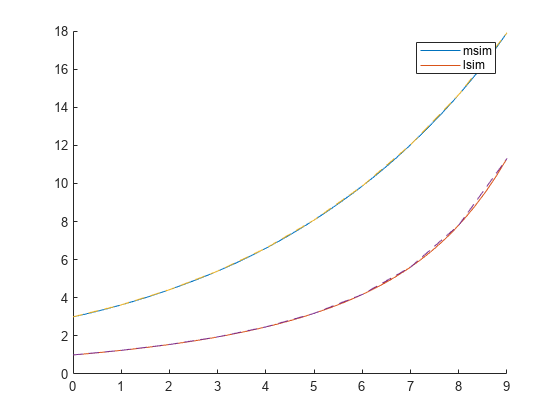

    [y_mlin,t_mlin,x_mlin] = msim(msys, u, t, x0);
    
    figure()
    hold on
    plot(t_mlin, y_mlin(:,:),'-')
    plot(t_lin, y_lin(:,:),'--')
    legend('msim', 'lsim')
    hold off

Step answer:

    A = [-1.5 -3; 3 -1];
    B = [1.3; 0];
    C = [1.15 2.3];
    D = [0];
    lsys = ss(A, B, C, D)

lsys =
 
  A = 
         x1    x2
   x1  -1.5    -3
   x2     3    -1
 
  B = 
        u1
   x1  1.3
   x2    0
 
  C = 
         x1    x2
   y1  1.15   2.3
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




    x0 = [-0.2 0.3];
    t = 0:0.05:8;
    u = zeros(length(1),1);
    u(t>=2) = 1;

    [y_lin, t_lin, x_lin] = lsim(lsys, u, t, x0, 'foh');

    F = CPN1(diag(ones([3,1])), [A, B]);
    G = CPN1(diag(ones([3,1])), [C, D]);
    
    msys = mss(F,G)

msys =   mss with properties:

        F: [1×1 norm1CPN]
        G: [1×1 norm1CPN]
        n: 2
        m: 1
        p: 1
    ntype: '1'
       ts: 0


    
    [y_mlin,t_mlin,x_mlin] = msim(msys, u', t, x0);
    
    y_lin_interp = interp1(t_lin, y_lin, t_mlin);
    [R,p] = corrcoef(y_mlin, y_lin_interp)

R =     1.0000    1.0000
    1.0000    1.0000


p =     1.0000    0.0000
    0.0000    1.0000



    figure()
    hold on
    p1 = plot(t_mlin, y_mlin(:,:),'-')

p1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0167 0.0335 0.0502 0.0670 0.1285 0.1901 0.2517 0.3132 0.3747 0.4362 0.4977 0.5592 0.6219 0.6847 0.7474 0.8102 0.8734 0.9367 0.9999 1.0632 1.1256 1.1880 1.2505 1.3129 1.3759 1.4390 1.5020 1.5651 1.6275 1.6900 1.7524 1.8149 … ]
              YData: [0.4600 0.4141 0.3689 0.3244 0.2809 0.1298 -0.0046 -0.1195 -0.2136 -0.2864 -0.3383 -0.3705 -0.3844 -0.3821 -0.3655 -0.3374 -0.3006 -0.2572 -0.2102 -0.1621 -0.1147 -0.0703 -0.0296 0.0062 0.0367 0.0615 0.0804 0.0935 0.1010 0.1035 … ]

  Show all pro

    p2 = plot(t_lin, y_lin(:,:),'--')

p2 =   Line with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '--'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0500 0.1000 0.1500 0.2000 0.2500 0.3000 0.3500 0.4000 0.4500 0.5000 0.5500 0.6000 0.6500 0.7000 0.7500 0.8000 0.8500 0.9000 0.9500 1 1.0500 1.1000 1.1500 1.2000 1.2500 1.3000 1.3500 1.4000 1.4500 1.5000 1.5500 1.6000 1.6500 … ]
              YData: [0.4600 0.3251 0.1980 0.0809 -0.0243 -0.1166 -0.1952 -0.2597 -0.3103 -0.3473 -0.3714 -0.3835 -0.3847 -0.3764 -0.3597 -0.3362 -0.3071 -0.2739 -0.2378 -0.2002 -0.1620 -0.1243 -0.0880 -0.0538 -0.0223 0.0061 0.0310 0.0522 0.0696 … ]

  Show al

    p3 = plot(t, u, '-')

p3 =   Line with properties:

              Color: [0.9290 0.6940 0.1250]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0500 0.1000 0.1500 0.2000 0.2500 0.3000 0.3500 0.4000 0.4500 0.5000 0.5500 0.6000 0.6500 0.7000 0.7500 0.8000 0.8500 0.9000 0.9500 1 1.0500 1.1000 1.1500 1.2000 1.2500 1.3000 1.3500 1.4000 1.4500 1.5000 1.5500 1.6000 1.6500 … ]
              YData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 … ]

  Show 

    p3.Color = [0.6 0.6 0.6;]

p3 =   Line with properties:

              Color: [0.6000 0.6000 0.6000]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0500 0.1000 0.1500 0.2000 0.2500 0.3000 0.3500 0.4000 0.4500 0.5000 0.5500 0.6000 0.6500 0.7000 0.7500 0.8000 0.8500 0.9000 0.9500 1 1.0500 1.1000 1.1500 1.2000 1.2500 1.3000 1.3500 1.4000 1.4500 1.5000 1.5500 1.6000 1.6500 … ]
              YData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 … ]

  Show 

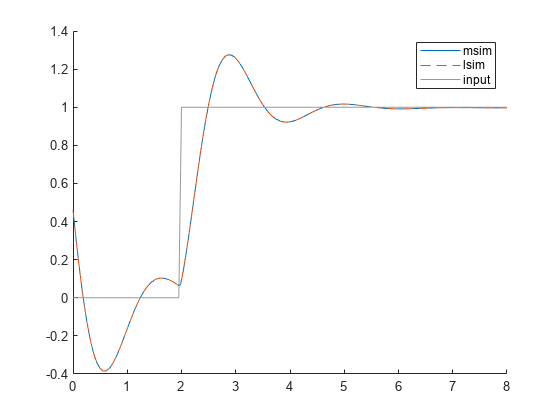

    legend('msim', 'lsim', 'input')
    hold off

legacyFunctions

        function [y,x] = legacyMsim(msys,u,t,x0)
            %function [y,x] = msim(msys,u,t,x0)
            % discrete-time simulation for multilinear CPN-1 models
            % focus large scale, high effiency
            % best if factor matrices are sparse logical
            %
            % gerwald.de
            % 3.11.2022

            % get dimensions
            [n rf] = size(msys.F.phi);         % number of states
            [p rg] = size(msys.G.phi);         % number of outputs
            m = size(msys.F.U,1)-n;         % number of inputs
            if size(msys.G.U,1)-n ~= m
                error('size mismatch')
            end
            % Initialize result matrices
            if length(t)==1
                T = t;
                t = 1:T;
            else
                T = t(end);
            end
            if nargout>1
                x = zeros(n,T);
            else
                x = zeros(n,1);
            end
            x(:,1)= x0(:);
            y = zeros(p,T);

            % get factor matrix indices and values (only if double)
            if islogical(msys.F.U)
                [rfi,cfi] = find(msys.F.U);
                lfi = true;
            else
                [rfi,cfi,vfi] = find(msys.F.U);
                sfi = -sign(vfi);  % sign vector of non-zero elements
                lfi = false;
            end
            if islogical(msys.G.U)
                [rgi,cgi] = find(msys.G.U);
                lgi = true;
            else
                [rgi,cgi,vgi] = find(msys.G.U);
                sgi = -sign(vgi);  % sign vector of non-zero elements
                lgi = false;
            end

            kx = 1;
            kxp = 1;

            % discrete time simulation
            for k = t
                % index only needed for 2nd output arg (state trajectory)
                if nargout>1
                    kx = k;
                    kxp = k+1;
                end
                % stack state-input vector
                xu = [x(:,kx);u(:,k)];
                % compute output
                if lgi   % Boolean
                    y(:,k) = msys.G.phi*accumarray(cgi,xu(rgi),[rg 1],@prod,1);
                else     % Double
                    y(:,k) = msys.G.phi*accumarray(cgi,1+vgi.*(xu(rgi)+sgi),[rg 1],@prod,1);
                end
                % compute next state
                if lfi   % Boolean
                    x(:,kxp) = msys.F.phi*accumarray(cfi,xu(rfi),[rf 1],@prod,1);
                else    % Double
                    x(:,kxp) = msys.F.phi*accumarray(cfi,1+vfi.*(xu(rfi)+sfi),[rf 1],@prod,1);
                end
            end

        end


        function sys = drmss(n,p,m,r,s,b)
            %DRMSS  Generate random discrete-time multilinear state-space models.

            if nargin < 1
                n=max([1,round(abs(10*randn(1,1)))]);
            end
            if nargin < 2
                p=1;
            end
            if nargin < 3
                m=1;
            end
            if nargin < 4
                r=round(n+m)/2;
            end
            if nargin < 5
                s = 0.2;
            end
            if nargin < 6
                b = false
            end

            sys.n = n;
            sys.F.ntype = 1;
            sys.F.U = sprand(n+m,r,s);
            if b
                sys.F.U = sys.F.U>0;
            end
            sys.F.phi = sprand(n,r,0.7);

            sys.G.ntype = 1;
            sys.G.U = sprand(n+m,r,s);
            if b
                sys.G.U = sys.G.U>0;
            end
            sys.G.phi = sprand(p,r,0.7);


        end
